Aerofoil

## **Aerofoil shape**

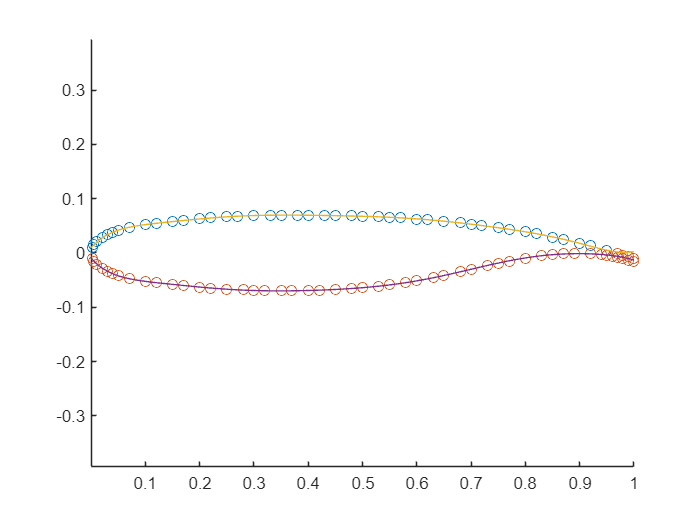

SC20714Shape = [1.000  -.0104
0.99    -.0071
0.98    -.0039
0.97    -.0009
0.95    .0049
0.92    .0131
0.9      .0181
0.87    .0251
0.85    .0294
0.82    .0353
0.800  .0389
0.77    .0439
0.75    .0469
0.72    .0509
0.7      .0533
0.68    .0555
0.65    .0585
0.62    .0610
0.6      .0625
0.57    .0645
0.55    .0656
0.53    .0666
0.50    .0678
0.48    .0684
0.45    .0692
0.43    .0695
0.4      .0697
0.38    .0698
0.35    .0696
0.33    .0692
0.3      .0685
0.27    .0673
0.25    .0664
0.22    .0646
0.2      .0632
0.17    .0606
0.15    .0585
0.12    .0548
0.1      .0518
0.07    .0462
0.05    .0411
0.04    .0381
0.03    .0343
0.02    .0293
0.01    .0219
0.005  .0158
0.002  .0095
0.00    .00
0.002  -.0093
.005    -.016
0.01    -.0221
0.02    -.0295
0.03    -.0344
0.04    -.0381
0.05    -.0412
0.07    -.0462
0.1      -.0517
0.12    -.0547
0.15    -.0585
0.17    -.0606
0.20    -.0633
0.22    -.0647
0.25    -.0666
0.28    -.068
0.3      -.0687
0.32    -.0692
0.35    -.0696
0.37    -.0696
0.4      -.0692
0.42    -.0688
0.45    -.0676
0.48    -.0657
0.5      -.0644
0.53    -.0614
0.55    -.0588
0.58    -.0543
0.6      -.0509
0.63    -.0451
0.65    -.041
0.68    -.0346
0.70    -.0302
0.73    -.0235
0.75    -.0192
0.77    -.0150
0.80    -.0093
0.83    -.0048
0.85    -.0024
0.87    -.0013
0.89   -.0008
0.92    -.0016
0.94    -.0035
0.95    -.0049
0.96    -.0066
0.97    -.0085
0.98    -.0109
0.99    -.0137
1.0      -.0163];

% Separate x and y coordinates
x_coords = SC20714Shape(:, 1);
y_coords = SC20714Shape(:, 2);

y_upperIdx = find(y_coords > 0);
y_lowerIdx = find(y_coords < 0);

figure(1)
clf;
scatter(x_coords(y_upperIdx), y_coords(y_upperIdx))
hold on
scatter(x_coords(y_lowerIdx), y_coords(y_lowerIdx))

y_upperfun = polyfit(x_coords(y_upperIdx), y_coords(y_upperIdx),9);
y_lowerfun = polyfit(x_coords(y_lowerIdx), y_coords(y_lowerIdx),9);

hold on
x_c = linspace(0,1,100);
plot(x_c, polyval(y_upperfun, x_c))
hold on
plot(x_c, polyval(y_lowerfun, x_c))
hold on
axis equal

t_cfun = @(x_c) polyval(y_upperfun, x_c) - polyval(y_lowerfun, x_c)

t_cfun = function_handle with value:
    @(x_c)polyval(y_upperfun,x_c)-polyval(y_lowerfun,x_c)


Chord location of maximum thickness

thickness_values = arrayfun(t_cfun, x_c);
[max_thickness, max_index] = max(thickness_values);
x_cm = x_c(max_index)

x_cm = 0.3535

Thickness-chord-ratio

t_c = max(t_cfun(x_c))

t_c = 0.1396

Wing Definition:

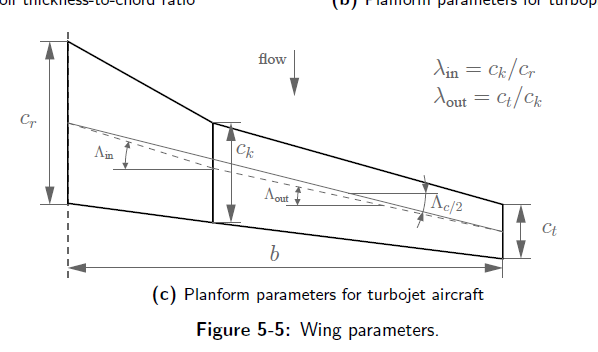

Define wing:

wing = WingGeometry();
wing.cr = 11;
wing.ck = 6;
wing.ct = 4;
wing.b = 65/2;
wing.Lambdain50 = 35*pi/180;
wing.Lambdaout50 = 26*pi/180;
wing.yk = wing.b*0.3;
wing = wing.calcSref()

wing =   WingGeometry with properties:

             cr: 11
             ck: 6
             ct: 4
              b: 32.5000
             yk: 9.7500
     Lambdain50: 0.6109
    Lambdaout50: 0.4538
           Sref: 196.6250
            Nin: []
           Nout: []
             Sc: []
         stripy: []
             AR: 5.3719
            Sin: 82.8750
           Sout: 113.7500


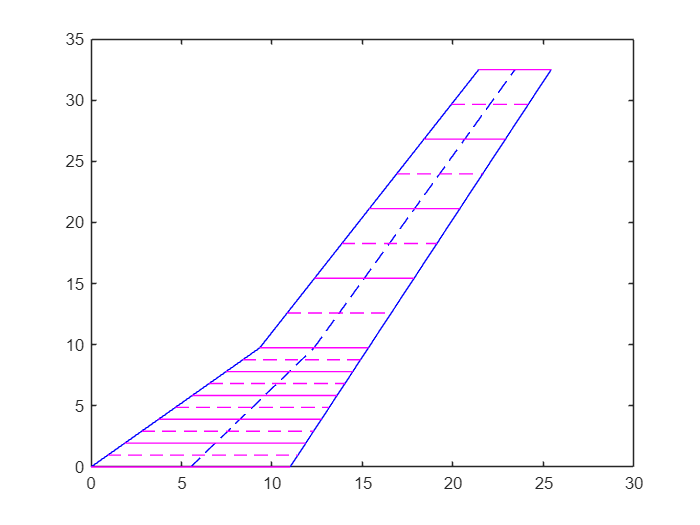

wing.Nin = 5;
wing.Nout = 4;
figure(1)
clf;
axis equal
wing.plotWing()
wing.c_at_y(10);
wing = wing.createStrips();
wing.plotStrips();

wing = wing.calcSc()

wing =   WingGeometry with properties:

             cr: 11
             ck: 6
             ct: 4
              b: 32.5000
             yk: 9.7500
     Lambdain50: 0.6109
    Lambdaout50: 0.4538
           Sref: 196.6250
            Nin: 5
           Nout: 4
             Sc: [10.2375 9.2625 8.2875 7.3125 6.3375 16.3516 14.9297 13.5078 12.0859]
         stripy: [0.9750 2.9250 4.8750 6.8250 8.7750 12.5938 18.2812 23.9688 29.6562]
             AR: 5.3719
            Sin: 82.8750
           Sout: 113.7500


Cruise Condition

%Chord length
c = 4;
h = convlength(39000, 'ft','m');
[T, a, P, rho, nu, mu] = atmosisa(h);
M = 0.83;
V = M * a;
Re = rho*V*c/mu

Re = 2.1804e+07

Swet_SrefWing = 2.2;
Swet_SrefBody = 5;
l_d = 10;

## Drag Model, Ref15

## Friction Drag

CDF = CDFfun(M, Re, wing, x_cm, t_c, l_d, Swet_SrefWing, Swet_SrefBody)

CDF = 0.0152

## Wave Drag

function Cl = Clfun(y)
    Cl = 0.7*y/y;
end

Integration of drag produced by each strip gives the total wave drag coefficient

CDW = CDWfun(wing,@Clfun,M,t_c)

Function definitions in a script must appear at the end of the file.
Move all statements after the "Clfun" function definition to before the first local function definition.

CDW = 0.0051

## Wing Weight

W_crew = 500 * 82.8;                     % Passenger weight + carry-on luggage (kg) % Ref 04 p.45
W_crew = W_crew + (12 + 4) * 79.4;       % Crew weight + carry-on luggage (kg)      % Roskam Part I p.8
W_payload = 500 * 17;                    % Passener checked luggage (kg)            % Ref 04 p.45
W_payload = W_payload + (12 + 4) * 13.6; % Crew checked luggage (kg)                % Roskam Part I p.8
Wpay = 9.81*(W_crew + W_payload)

Wpay = 5.0412e+05

Wto = 4.3895*1e5*9.81

Wto = 4.3061e+06

nult = 3.75; %Chatgpt, b777
range = convlength(7500, 'naut mi','m');

Ww = wingWeightLTH(wing,t_c,Wto)

Ww = 1.7463e+05

mw = 1.7802e+04

%Ww = wingWeightHowe(wing,Wpay,Wto,nult,t_c,V,range*1e03)
mw = Ww/9.81 %one wing